# Markov process

## Clean variables

clc, clear all, close all;
syms y_o z_o k;
syms s;

## Generamos la matrix de markov

A = [0.9,0.2;...
     0.1,0.8];
 u = [y_o;z_o]

$$u = \left(\begin{array}{c} y_{o}\\ z_{o} \end{array}\right)$$

 [Vectors,values] = eig(A)

Vectors =     0.8944   -0.7071
    0.4472    0.7071


values =     1.0000         0
         0    0.7000


 aux_det = det(A-s*eye(2))

$$aux\_det = s^{2}-\frac{17\,s}{10}+\frac{7}{10}$$

 solve(aux_det,s)

$$ans = \left(\begin{array}{c} \frac{7}{10}\\ 1 \end{array}\right)$$

 A-eye(2)

ans =    -0.1000    0.2000
    0.1000   -0.2000


## Descomposicion Jordan

[V,J] = jordan(A)

V =     -1     2
     1     1


J =     0.7000         0
         0    1.0000


V_1 = inv(V)

V_1 =    -0.3333    0.6667
    0.3333    0.3333



D_k = J^(k)

$$D\_k = \left(\begin{array}{cc} {\left(\frac{7}{10}\right)}^{k} & 0\\ 0 & 1 \end{array}\right)$$

entrada = V_1*u

$$entrada = \left(\begin{array}{c} \frac{2\,z_{o}}{3}-\frac{y_{o}}{3}\\ \frac{y_{o}}{3}+\frac{z_{o}}{3} \end{array}\right)$$


solucion = expand(V*D_k*entrada)

$$solucion = \left(\begin{array}{c} \frac{2\,y_{o}}{3}+\frac{2\,z_{o}}{3}+\frac{{\left(\frac{7}{10}\right)}^{k}\,y_{o}}{3}-\frac{2\,{\left(\frac{7}{10}\right)}^{k}\,z_{o}}{3}\\ \frac{y_{o}}{3}+\frac{z_{o}}{3}-\frac{{\left(\frac{7}{10}\right)}^{k}\,y_{o}}{3}+\frac{2\,{\left(\frac{7}{10}\right)}^{k}\,z_{o}}{3} \end{array}\right)$$



auto_vector = [2;1]

auto_vector =      2
     1


A*auto_vector

ans =      2
     1


## Simulation syste

t = (0:0.1:10)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



U = [0.7;0.3];
Markov_matrix = [0.9,0.2;0.1,0.8]

Markov_matrix =     0.9000    0.2000
    0.1000    0.8000


Markov_matrix^(length(t))*U

ans =     0.6667    0.6667
    0.3333    0.3333


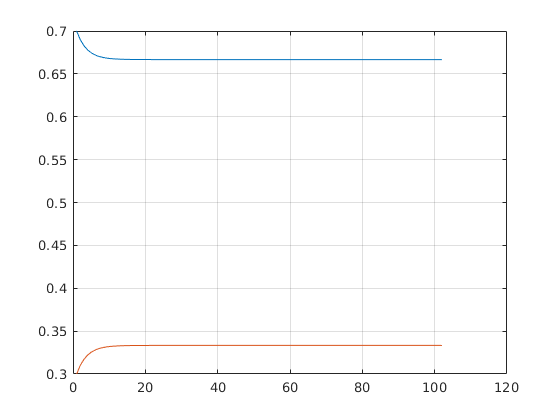

for k =1:length(t)
    U(:,k+1) = Markov_matrix*U(:,k); 
end
figure
plot(U(1,:))
hold on;
plot(U(2,:))
grid on

## Valores solucion por frobenius

auto_vectores = [2,-1;1,1]

auto_vectores =      2    -1
     1     1


a_valores = inv(auto_vectores)*U(:,1)

a_valores =     0.3333
   -0.0333


a_valores(1)*auto_vectores(:,1)

ans =     0.6667
    0.3333
